# Coursework - Optimisation, Filtering and Fusion

## Task I

### Upload the Data

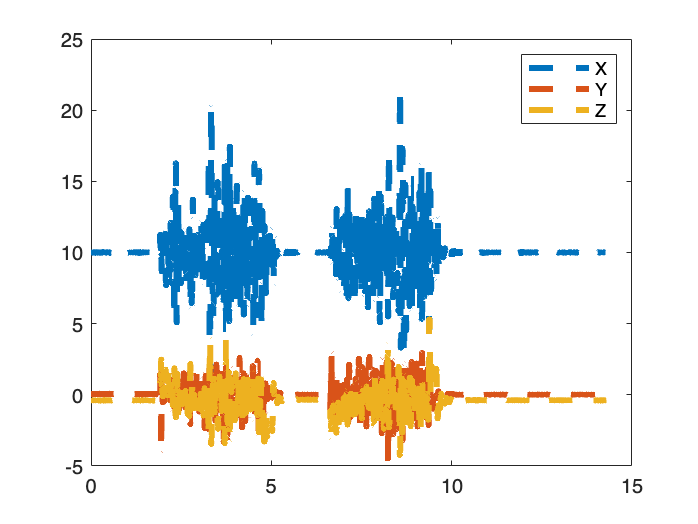

clear; clc; clf;
load("trainingData/calib1_rotate.mat")
load("trainingData/calib2_straight.mat")
load("trainingData/task1_1.mat")
% load("trainingData/task1_2.mat")
% load("trainingData/task1_3.mat")
% load("trainingData/task1_4.mat")
% load("trainingData/task1_5.mat")

% N x 1
% Updates @ 200Hz
tIMU = out.Sensor_Time.time;

% 1 x 3 x N
% Updates @ 104Hz
accelRaw = squeeze(out.Sensor_ACCEL.signals.values)';
accelLPRaw = squeeze(out.Sensor_LP_ACCEL.signals.values)';

% 1 x 3 x N
% Updates @ 104Hz
gyroRaw  = squeeze(out.Sensor_GYRO.signals.values)';

% 1 x 3 x N
% Updates @ 50
magRaw   = squeeze(out.Sensor_MAG.signals.values)';

% N x 4
% Updates @ 10Hz
% [dist, ambient, signal, status]
% Status: 0=Probably too close but OK, 2=Long OK, 4=Short OK
ToF1     = out.Sensor_ToF1.signals.values;
ToF2     = out.Sensor_ToF2.signals.values;
ToF3     = out.Sensor_ToF3.signals.values;

% N x 1
gt_time = out.GT_time.time;
% N x 3
% Updates @ 200Hz
gt_pos   = out.GT_position.signals.values;
% N x 4
% Updates @ 200Hz
gt_quat  = out.GT_rotation.signals.values;

plot(tIMU, accelRaw(:, 1), LineWidth=3, LineStyle="--");
hold on;
plot(tIMU, accelRaw(:, 2), LineWidth=3, LineStyle="--");
plot(tIMU, accelRaw(:, 3), LineWidth=3, LineStyle="--");
legend(["X", "Y", "Z"]);